# 案例分析：二次插值法求解极值

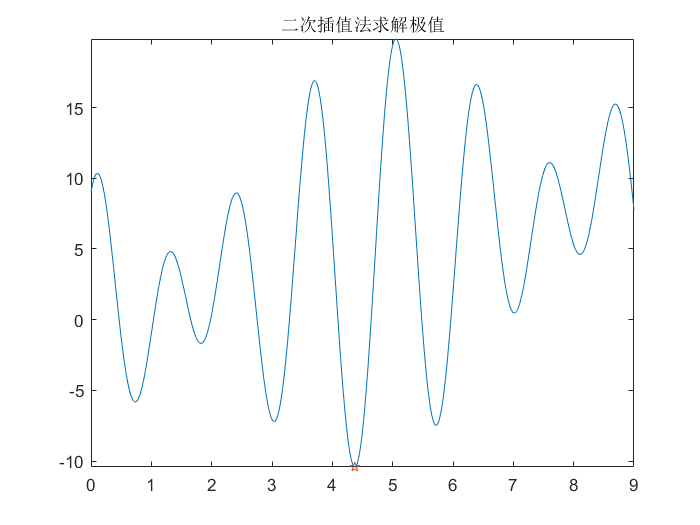

clear; clc;
fun = @(x) x + 6 * sin(4 * x) + 9 * cos(5 * x);
x0 = OptQuadratic(fun, 0, 9, 1e-6, 1000);
fplot(fun, [0, 9])
hold on 
plot(x0, fun(x0), 'p');
hold off
title('二次插值法求解极值');

function x0 = OptQuadratic(func, a, b, err, MaxIter)
%{
函数功能：二次插值法求解极值
输入：
  func：目标函数句柄；
  a：左端点值；
  b：右端点值；
  err：精度阈值；
  MaxIter：最大迭代次数；
输出：
  x0：最小值点；
%}
if nargin < 5
   MaxIter = 1000;
end
if nargin < 4
   err = 1e-6;
end
if nargin < 3
   error('输入参数不足！');
end
% 初始情况
t0 = (a + b)/2;
tol = 1;
ite = 0;
while tol > err && ite < MaxIter 
    fa = func(a);
    fb = func(b);
    ft0 = func(t0);
    tu = fa*(b^2 - t0^2) + fb*(t0^2 - a^2) + ft0*(a^2 - b^2);
    td = fa*(b - t0) + fb*(t0 - a) + ft0*(a - b);
    t1 = tu/(2*td);
    ft1 = func(t1);
    tol = abs(t1 - t0);
    if ft1 <= ft0
        if t1<= t0
            b = t0;
            t0 = t1;
        else
            a = t0;
            t0 = t1;
        end
    else
       if t1<= t0
           a = t1;
       else
           b = t1;
       end
    end
    ite = ite + 1;
    if ite == MaxIter
       disp('没有找到最小值！');
       x0 = NaN;
       return;
    end
end
x0 = t1;
end